% Tamanho do Bloom Filter e número de funções de dispersão
n = 8000;
k = 3;

% Inicializar o Bloom Filter
bloomFilter = initializeBloomFilter(n, k);

% Ler text
fileID = fopen('wordlist-preao-20201103.txt', 'r');
wordlist = textscan(fileID, '%s');
fclose(fileID);

% Subconjunto de 1000 palavras diferentes para U1
U1 = wordlist{1}(1:1000);

% Inserir palavras de U1 no Bloom Filter
for i = 1:length(U1)
    bloomFilter = insertElement(bloomFilter, U1{i}, k);
end

% Verificar a pertinência das palavras de U1 no Bloom Filter
for i = 1:length(U1)
    isMember = checkMembership(bloomFilter, U1{i}, k);
    fprintf('A palavra %s pertence ao conjunto U1: %d\n', U1{i}, isMember);
end

A palavra AAC pertence ao conjunto U1: 1
A palavra ABC pertence ao conjunto U1: 1
A palavra ACP pertence ao conjunto U1: 1
A palavra AD pertence ao conjunto U1: 1
A palavra ADN pertence ao conjunto U1: 1
A palavra ADSL pertence ao conjunto U1: 1
A palavra AFP pertence ao conjunto U1: 1
A palavra AML pertence ao conjunto U1: 1
A palavra AMP pertence ao conjunto U1: 1
A palavra ANACOM pertence ao conjunto U1: 1
A palavra ANC pertence ao conjunto U1: 1
A palavra ANMP pertence ao conjunto U1: 1
A palavra APEL pertence ao conjunto U1: 1
A palavra API pertence ao conjunto U1: 1
A palavra APL pertence ao conjunto U1: 1
A palavra APPACDM pertence ao conjunto U1: 1
A palavra ARS pertence ao conjunto U1: 1
A palavra ASAE pertence ao conjunto U1: 1
A palavra ASCII pertence ao conjunto U1: 1
A palavra AVC pertence ao conjunto U1: 1
A palavra Aachen pertence ao conjunto U1: 1
A palavra Aalborg pertence ao conjunto U1: 1
A palavra Aarhus pertence ao conjunto U1: 1
A palavra Abecassis pertence ao con




% Teste de Falsos Negativos (Alinea 2)
false_negatives = 0;

% Itera sobre todas as palavras em U1
for i = 1:length(U1)
    isMember = checkMembership(bloomFilter, U1{i}, k);

    % Se não pertence, registra um falso negativo
    if ~isMember
        false_negatives = false_negatives + 1;
        fprintf('Falso Negativo: A palavra %s não foi detectada no conjunto U1\n', U1{i});
    end
end

% Verifica se algum falso negativo foi encontrado
if false_negatives == 0
    fprintf('Não foram encontrados falsos negativos.\n');
else
    fprintf('Número total de falsos negativos: %d\n', false_negatives);
end

Não foram encontrados falsos negativos.






% Alinea 3 - Teste do Bloom Filter com U2 e Cálculo de Falsos Positivos
U2 = chooseUniqueWords(wordlist{1}, 1000, U1);

% Testa o Bloom Filter com U2 e calcule a percentagem de falsos positivos
false_positives = 0;

for i = 1:length(U2)
    isMember = checkMembership(bloomFilter, U2{i}, k);
    
    % Se o Bloom Filter indicar pertinência, mas a palavra não está em U1
    if isMember && ~ismember(U2{i}, U1)
        false_positives = false_positives + 1;
    end
end

% Calcule a percentagem de falsos positivos
total_words_U2 = length(U2);
false_positive_percentage = (false_positives / total_words_U2) * 100;

% Imprimir a percentagem de falsos positivos
fprintf('\nPercentagem de Falsos Positivos para U2: %.2f%%\n', false_positive_percentage);


Porcentagem de Falsos Positivos para U2: 10.70%


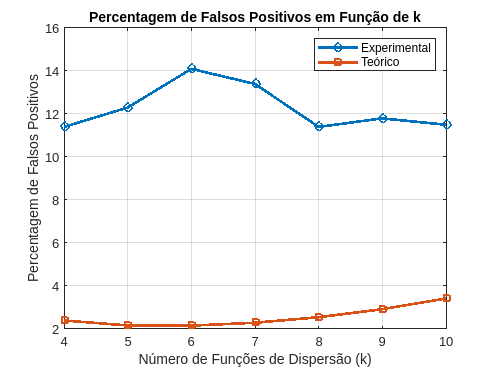

% Tamanho do Bloom Filter
n = 8000;

% Número de funções de dispersão (varie de 4 a 10)
k_values = 4:10;

% Inicializar o Bloom Filter para cada valor de k
false_positive_percentages = zeros(size(k_values));

% Cálculo teórico da probabilidade de falsos positivos (slides Tp)
theoretical_false_positives = zeros(size(k_values));

for j = 1:length(k_values)
    k = k_values(j);

    % Valor teórico da probabilidade de falsos positivos
    theoretical_false_positives(j) = (1 - (1 - 1/n) ^ (k * 1000)) ^ k;

    bloomFilter = initializeBloomFilter(n, k);

    % Insira as palavras de U1 no Bloom Filter
    for i = 1:length(U1)
        bloomFilter = insertElement(bloomFilter, U1{i}, k);
    end

    % Gere o conjunto U2 para cada valor de k
    U2 = chooseUniqueWords(wordlist{1}, 1000, U1);

    % Testa o Bloom Filter com U2 e calcule a percentagem de falsos positivos
    false_positives = 0;

    for i = 1:length(U2)
        isMember = checkMembership(bloomFilter, U2{i}, k);

        % Se o Bloom Filter indicar pertinência, mas a palavra não está em U1
        if isMember && ~ismember(U2{i}, U1)
            false_positives = false_positives + 1;
        end
    end

    % Calcule a percentagem de falsos positivos
    total_words_U2 = length(U2);
    false_positive_percentages(j) = (false_positives / total_words_U2) * 100;
end

% Crie um gráfico da percentagem de falsos positivos em função de k
figure;
plot(k_values, false_positive_percentages, '-o', 'LineWidth', 2, 'DisplayName', 'Experimental');
hold on;
plot(k_values, theoretical_false_positives * 100, '-s', 'LineWidth', 2, 'DisplayName', 'Teórico');
xlabel('Número de Funções de Dispersão (k)');
ylabel('Percentagem de Falsos Positivos');
title('Percentagem de Falsos Positivos em Função de k');
legend('show');
grid on;


%nao consegui perceber porque o experimental da me mal.